expriment 2-3,2-4

Mohamd Hosein Zanganeh

Mohamad Javad Zeinoddini

close all;
clear;
clc;

without noise 

2-3(a)

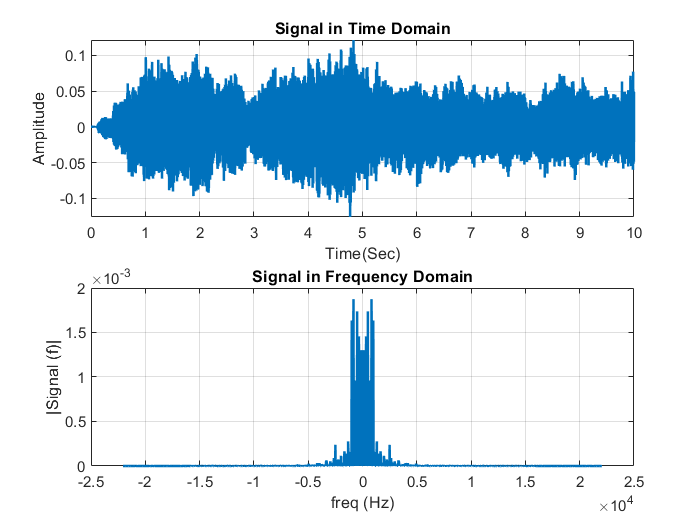


%2.3.a

[x, Fs] = audioread('Audio01.wav');
T = 10;
t = 0: 1/Fs:T-1/Fs;
L_x       = length(x);
f_x       = (Fs/L_x) * (-L_x/2:L_x/2-1);
fft_x     = fftshift(fft(x))/L_x;

figure(7);
subplot(2, 1, 1);
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Time(Sec)') ;
ylabel('Amplitude') ;
title('Signal in Time Domain');

subplot(2,1,2) ;
plot(f_x, abs(fft_x), 'LineWidth',1.5) ;
grid on;
xlabel('freq (Hz)');
ylabel('|Signal (f)|');
title('Signal in Frequency Domain');

2-3(b)

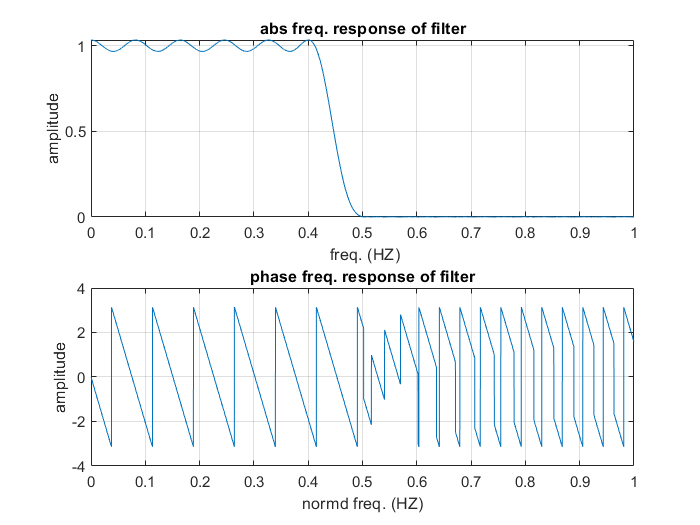

load('Filterlpf.mat');
[h , w] = freqz(Filterlpf);
figure('Name','freq. respons of filter')
subplot(2,1,1)
plot(w/pi , abs(h))
title('abs freq. response of filter');
xlabel(" freq. (HZ)");
ylabel("amplitude");
grid on;


subplot(2,1,2)
plot(w/pi , angle(h))
title('phase freq. response of filter');
xlabel("normd freq. (HZ)");
ylabel("amplitude");
grid on;

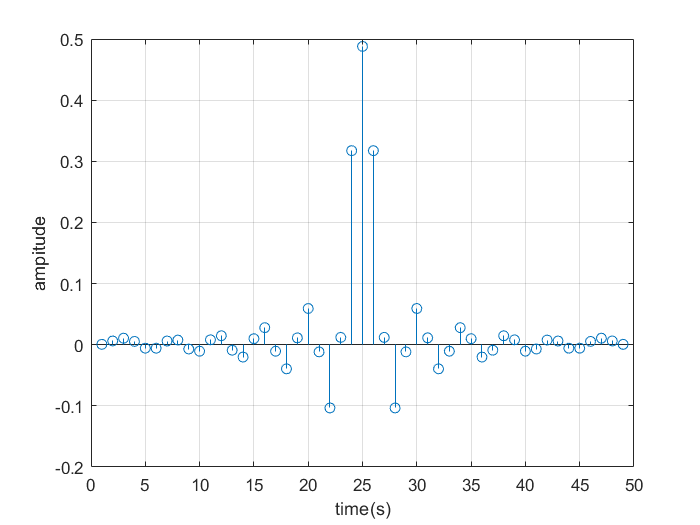



% time domain of filter
figure('Name','time domain resp. of filter');
stem(Num2)
xlabel('time(s)');
ylabel('ampitude');
grid on;

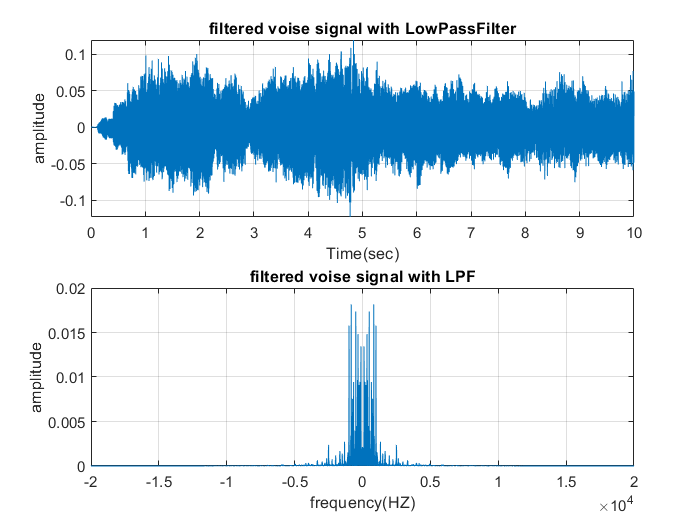

% 2-3(c)

f0 = 10000;
n = 1: length(t);
s_n = 2*cos( 2 * pi * f0 * n / Fs );
x_lpf = filter(Num2,1,x);
y1 = x_lpf.*s_n';
y2 = filter(Num2,1,y1);

% in frequency domain 

FT_x_lpf = (1/Fs)*fftshift(fft(x_lpf));
FT_y1 = (1/Fs)*fftshift(fft(y1));
FT_y2 = (1/Fs)*fftshift(fft(y2));

f_domain = linspace(-Fs / 2, Fs / 2, length(FT_y1));



figure('Name','voice scrambing and descrambing');
subplot(2,1,1)
plot(t,x_lpf);
title('filtered voise signal with LowPassFilter');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

subplot(2,1,2)
plot(f_domain,abs(FT_x_lpf));
title('filtered voise signal with LPF');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

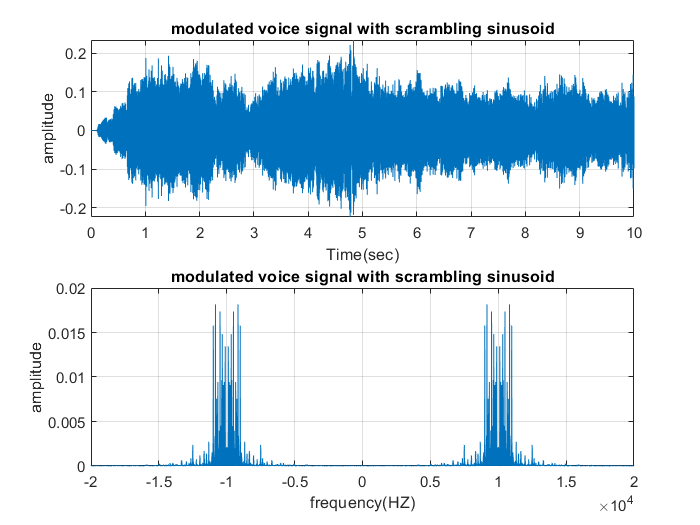

figure('Name','modulated voice signal with scrambling sinusoid');
subplot(2,1,1)
plot(t,y1);
title('modulated voice signal with scrambling sinusoid');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

subplot(2,1,2)
plot(f_domain,abs(FT_y1));
title('modulated voice signal with scrambling sinusoid');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

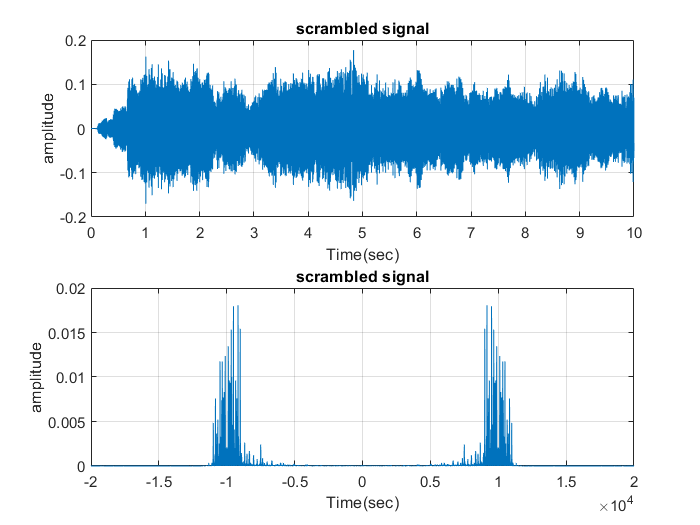

figure('Name','scrambled signal');
subplot(2,1,1)
plot(t,y2);
title('scrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;



subplot(2,1,2)
plot(f_domain,abs(FT_y2));
title('scrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

% sound(y2, Fs);
% pause(length(y2) / Fs);



2-3(d)

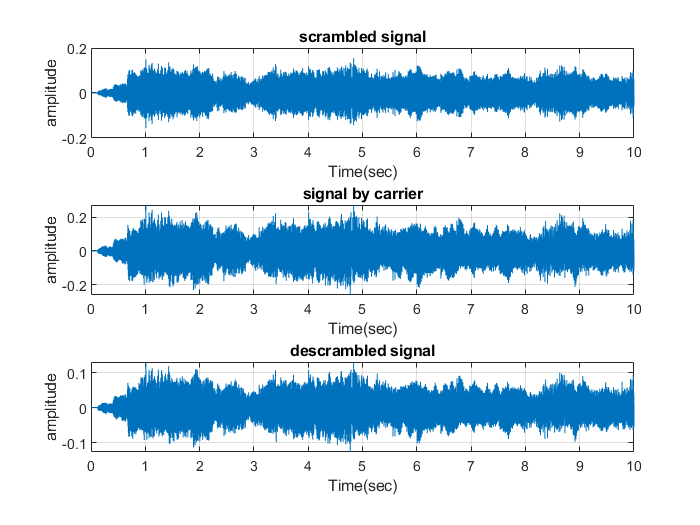

y_lowpassed = filter(Num2,1,y2);

y1_descrambling = y_lowpassed.*s_n';

y_descrambling = filter(Num2,1,y1_descrambling);

FT_y_lowpassed = (1/Fs)*fftshift(fft(y_lowpassed));
FT_y1_descrambling = (1/Fs)*fftshift(fft(y1_descrambling));
FT_y_descrambling = (1/Fs)*fftshift(fft(y_descrambling));

figure('Name','descrambled signal')
subplot(3,1,1)
plot(t,y_lowpassed);
title('scrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;
subplot(3,1,2)
plot(t,y1_descrambling);
title('signal by carrier');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;
subplot(3,1,3)
plot(t,y_descrambling);
title('descrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

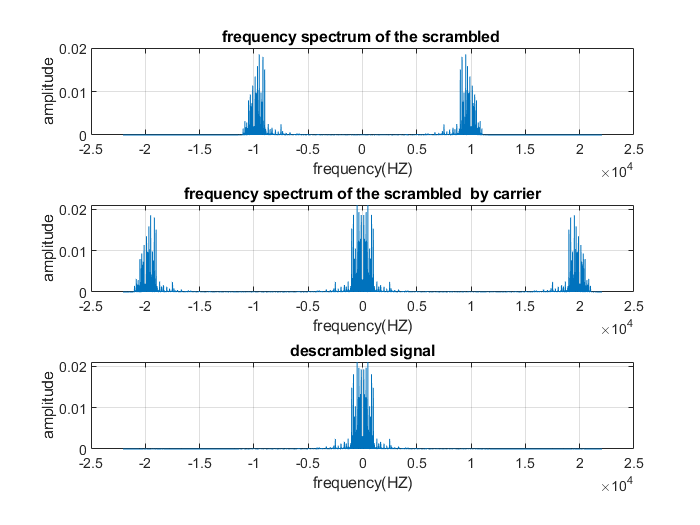

figure('Name','frequency spectrum descrambing');
subplot(3,1,1)
plot(f_domain,abs(FT_y_lowpassed));
title('frequency spectrum of the scrambled ');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2.5e4 2.5e4]);
grid on;
subplot(3,1,2)
plot(f_domain,abs(FT_y1_descrambling));
title('frequency spectrum of the scrambled  by carrier');
xlabel('frequency(HZ)');
ylabel('amplitude');

grid on;
subplot(3,1,3)
plot(f_domain,abs(FT_y_descrambling));
title('descrambled signal');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2.5e4 2.5e4]);
grid on;


% sound(y_descrambling,fs);
% pause(length(y_descrambling)/fs);

MAE = dot(abs(x - y_descrambling),ones(1,length(x)))/length(x);
MAE

MAE = 0.0310

MSE = dot((x - y_descrambling).^2,ones(1,length(x)))/length(x);
MSE

MSE = 0.0016

`noisy signal `

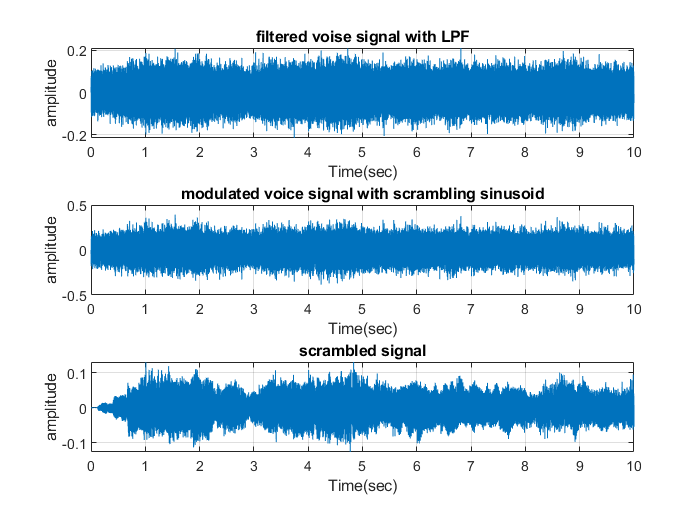


noise = randn(1,length(x))*0.05;

noisy_signal = y2.' + noise;
y_lowpassed = filter(Num2,1,noisy_signal);
y1_noisy_descrambling = y_lowpassed.*s_n;
y_noisy_descrambling = filter(Num2,1,y1_descrambling);

% in frequency domain 

FT_y_lowpassed = (1/Fs)*fftshift(fft(y_lowpassed));
FT_y1 = (1/Fs)*fftshift(fft(y1_noisy_descrambling));
FT_y2 = (1/Fs)*fftshift(fft(y_noisy_descrambling));

f_domain = linspace(-Fs / 2, Fs / 2, length(FT_y1));



figure('Name','voice scrambing and descrambing + noise');
subplot(3,1,1)
plot(t,y_lowpassed);
title('filtered voise signal with LPF');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

subplot(3,1,2)
plot(t,y1_noisy_descrambling);
title('modulated voice signal with scrambling sinusoid');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

subplot(3,1,3)
plot(t,y_noisy_descrambling);
title('scrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;

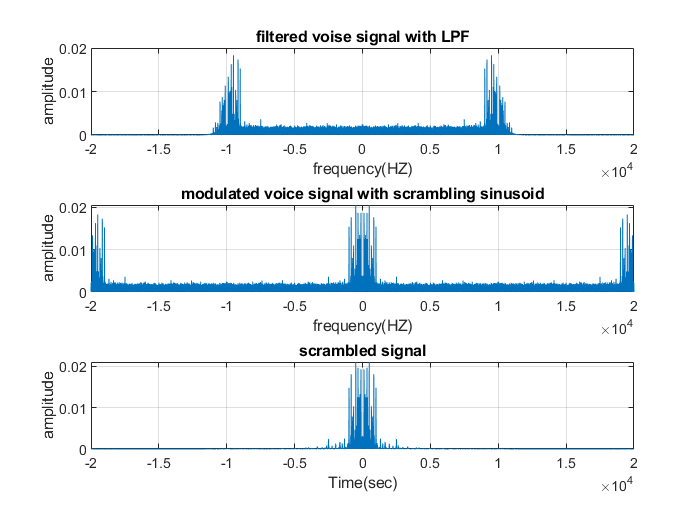


% sound(y_noisy_descrambling, fs);
% pause(length(y2) / fs);
% 

figure('Name','fft of voice scrambing and descrambing + noise');
subplot(3,1,1)
plot(f_domain,abs(FT_y_lowpassed));
title('filtered voise signal with LPF');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

subplot(3,1,2)
plot(f_domain,abs(FT_y1));
title('modulated voice signal with scrambling sinusoid');
xlabel('frequency(HZ)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

subplot(3,1,3)
plot(f_domain,abs(FT_y2));
title('scrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
xlim([-2e4 2e4]);
grid on;

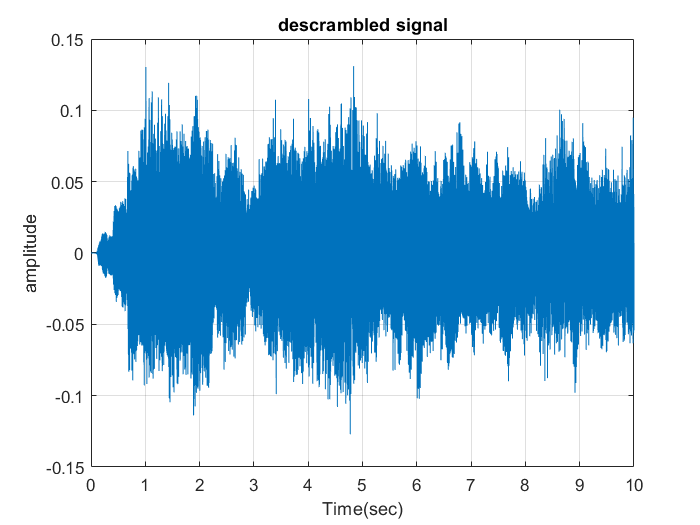


figure('Name','descrambled voice signal+ noise');
plot(t,y_noisy_descrambling);
title('descrambled signal');
xlabel('Time(sec)');
ylabel('amplitude');
grid on;


MAE = dot(abs(x - y_noisy_descrambling),ones(1,length(x)))/length(x);
MAE

MAE = 0.0310

MSE = dot((x - y_noisy_descrambling).^2,ones(1,length(x)))/length(x);
MSE

MSE = 0.0016

close all;
clear;
clc;

part(2-4)

2-4(a)

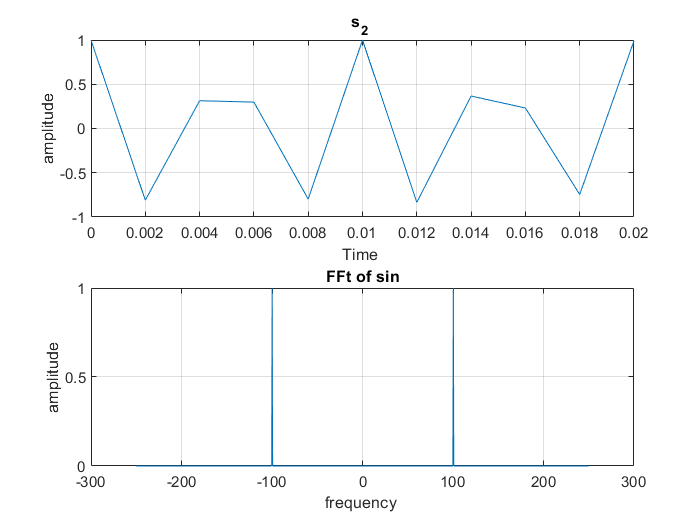


f0    = 100;
fs    = 500;
t_min = 0;
t_max = 2;
t     = t_min : 1/fs : t_max - 1/fs;
s_1   = sin(2 * pi * f0 * t);
f0    = 200;
f1    = 400;
s_2   = chirp(t,f0,t_max,f1); %chirp
s_3   = zeros(1,length(s_1)); %selta
s_3(250) = 50;
s     = s_1 + s_2 + s_3; %total





% s_1 sin
FT_s1 = fftshift(fft(s_1))*(1/fs);
fdomain_s1 = linspace(-fs / 2, fs / 2, length(FT_s1));
% s_2 chrip
FT_s2 = fftshift(fft(s_2))*(1/fs);
fdomain_s2 = linspace(-fs / 2, fs / 2, length(FT_s2));
% s_3 delta
FT_s3 = fftshift(fft(s_3))*(1/fs);
fdomain_s3 = linspace(-fs / 2, fs / 2, length(FT_s3));


% s total
FT_s = (1/fs)*fftshift(fft(s));
fdomain_s = linspace(-fs / 2, fs / 2, length(FT_s));









figure('Name','sin  s_1')
subplot(2,1,1)
plot(t,s_2)
title('s_2 ');
xlabel('Time ');
ylabel('amplitude');
xlim([0 0.02])
grid on;

subplot(2,1,2)
plot(fdomain_s1,abs(FT_s1))
title('FFt of sin');
xlabel('frequency ');
ylabel('amplitude');
xlim([-300 300])
grid on;

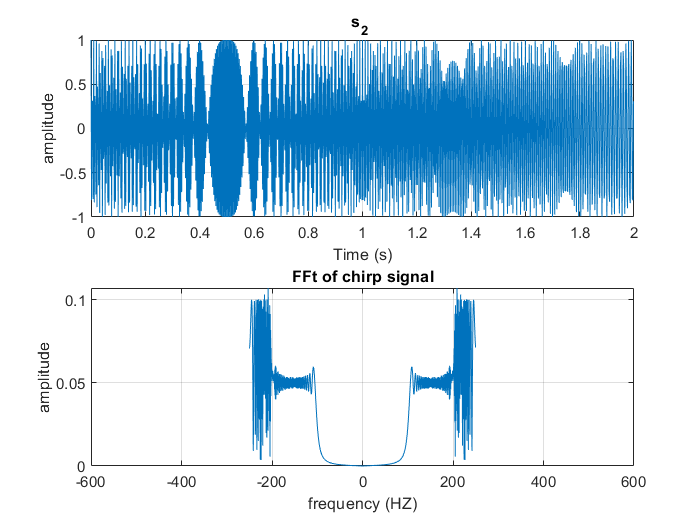




figure('Name',' chirp  s_2')
subplot(2,1,1)
plot(t,s_2)
title('s_2 ');
xlabel('Time (s)');
ylabel('amplitude');
grid on;

subplot(2,1,2)
plot(fdomain_s2,abs(FT_s2))
title('FFt of chirp signal');
xlabel('frequency (HZ)');
ylabel('amplitude');
xlim([-600 600])
grid on;

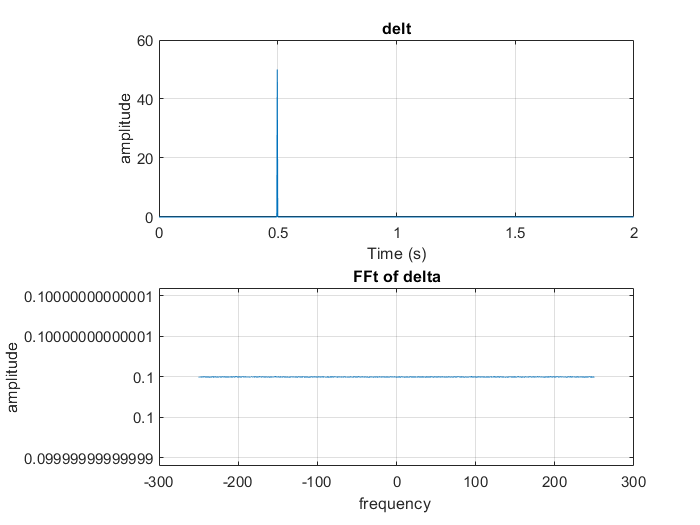






figure('Name','s_3')
subplot(2,1,1)
plot(t,s_3)
title('delt');
xlabel('Time (s)');
ylabel('amplitude');
% xlim([0 0.02])
grid on;

subplot(2,1,2)
plot(fdomain_s3,abs(FT_s3))
title('FFt of delta');
xlabel('frequency ');
ylabel('amplitude');
grid on;

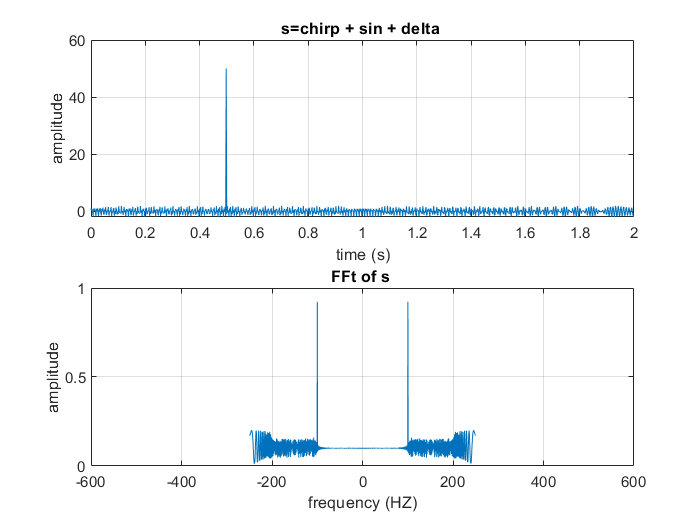





figure('Name','total signal')
subplot(2,1,1)
plot(t,s)
title('s=chirp + sin + delta ');
xlabel('time (s)');
ylabel('amplitude');
grid on;

subplot(2,1,2)
plot(fdomain_s,abs(FT_s));
title('FFt of s ');
xlabel('frequency (HZ)');
ylabel('amplitude');
xlim([-600 600]);
grid on;

2-4(b)

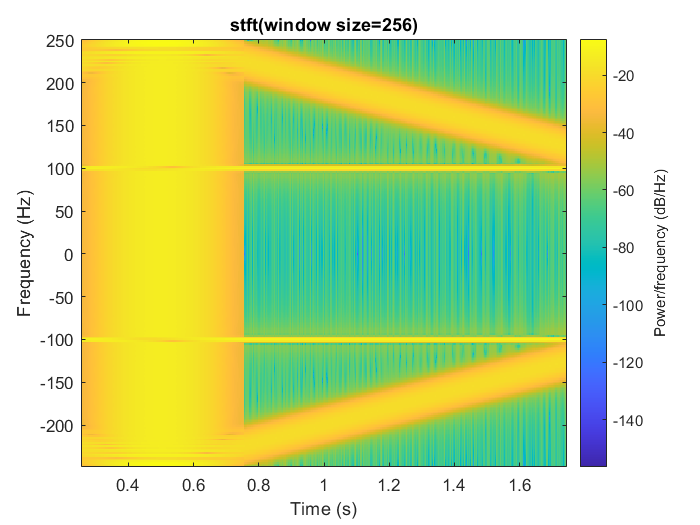

h1=hamming(256);
h2=hamming(512);

figure('Name','spectrogram of xt w = 256')
spectrogram(s,h1,255,256,fs,"centered",'yaxis');
title('stft(window size=256)');

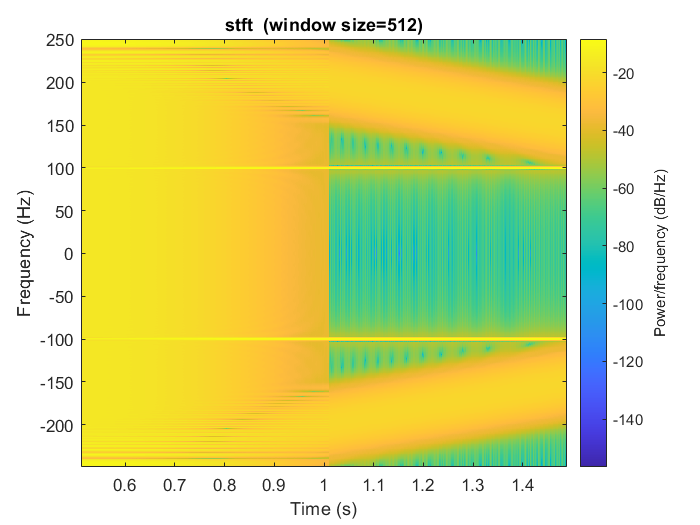


figure('Name','spectrogram of xt w=12')
spectrogram(s,h2,511,512,fs,"centered",'yaxis');
title('stft  (window size=512)');

the main difference between STFT and DTFT is that the DTFT provides a global view of the entire signal's frequency content across all frequencies, while the STFT provides a time-localized view of the signal's frequency content by analyzing short segments of the signal over time. The STFT is particularly useful for analyzing signals that change their frequency content over time, which is a common scenario in many real-world applications.

and 

When the window size becomes smaller:

Smaller window sizes result in better time resolution.

Smaller windows result in worse frequency resolution. 

And if we enlarge the window, the opposite happens.

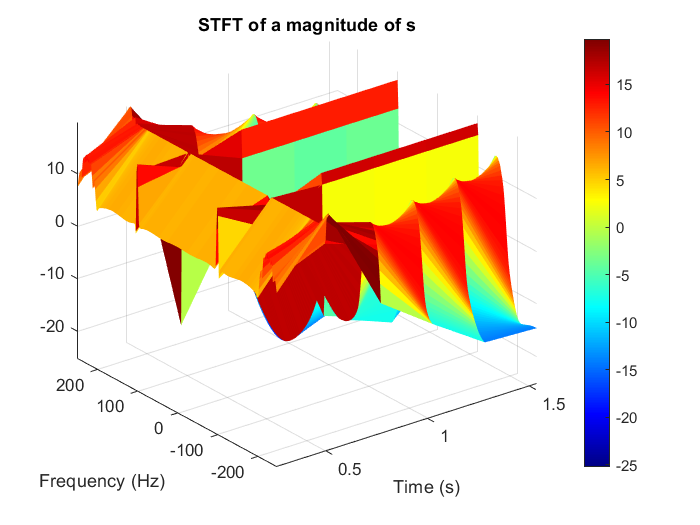

window_length = 256;
overlap_length = 128;

% Compute the STFT
[s, f, t] = stft(s, fs, 'Window', h1, 'OverlapLength', overlap_length, 'FFTLength', window_length);

% Create a 3D surface plot
figure('Name', 'Short-Time Fourier Transform');
surf(t, f, 10*log10(abs(s)), 'EdgeColor', 'none'); %The Bode magnitude
axis tight;
colormap(jet);
colorbar;
view(3); % 3D view for better visualization
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT of a magnitude of s');

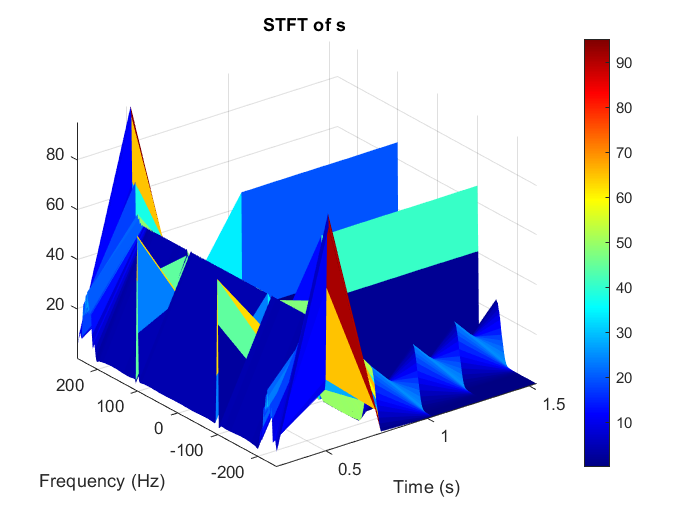



figure('Name', 'Short-Time Fourier Transform');
surf(t, f, abs(s), 'EdgeColor', 'none');
axis tight;
colormap(jet);
colorbar;
view(3); % 3D view for better visualization
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('STFT of s ');